This live script builds and validates principal component regression models that predict biomarker pigment concentrations from the 2nd spectral derivative of phytoplankton absorption coefficents.

We're using principal component regression for several reasons:

- in optical spectra observations at adjacent wavelengths are highly correlated with one another ("collinearity of predictors" problem in statistics speak)

- we can use all of the information contained in the spectrum rather than selecting a few (uncorrelated) regions that we suspect are most important

- restricting analysis to only leading principal components helps remove noise from the predictor data set

- we can reconstruct the model coefficients in our sample domain (it's not a black box!), which allows for more straightforward downstream analysis of how coefficients may interact with data quality issues, spatial or temporal bias in training data, etc.

We'll start by looking at how well we can predict 3 important pigments that show distinct trends in nature. We'll use a standard stepwise regression procedure for model selection and a cross-validation procedure to evaluate the quality of each modeling approach. To do this, the data are split randomly 75/25 into training/validation sets, model selection is performed on the training data, and the model is validated on the validation data. We repeat this 5 times to get a sense of how model performance might vary across different training sets: 

clear; close all;

% load aligned pigments and 2nd derivative spectra:
load('pnb_pigs_aph_2nd_deriv.mat');

% extract pigments you'd like to model:
fuco = pigs.Fuco;
mvchlb = pigs.MVChlb;
zea = pigs.Zea;

% set up for modeling:
% these parameters are going to be applied
mc = 100; % allow up to 100 pc's to be used as predictors
n_cv = 5; % do 5 cross-validations for each pigment
cv_frac = 0.75; % use 75% of the data set for training
% stepwise regression:
pred_select = 'stepwise';
mdl_select = 'AdjRsquared'; % use adjusted R2 to select model
[betas_fuco, alphas_fuco, summary_gofs_fuco, all_gofs_fuco, ~] = ...
    pig_from_aph_pcr_cv(d2, fuco,...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5


[betas_mvchlb, alphas_mvchlb, summary_gofs_mvchlb, all_gofs_mvchlb, ~] = ...
    pig_from_aph_pcr_cv(d2, mvchlb,...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5


[betas_zea, alphas_zea, summary_gofs_zea, all_gofs_zea, ~] = ...
    pig_from_aph_pcr_cv(d2, zea,...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5



disp(summary_gofs_fuco)

    Mean_R2     SD_R2      Mean_RMSE    SD_RMSE    Mean_mean_pct_error    SD_mean_pct_error    Mean_median_pct_error    SD_median_pct_error    Mean_pct_bias    SD_pct_bias
    _______    ________    _________    _______    ___________________    _________________    _____________________    ___________________    _____________    ___________

    0.83291    0.037445     0.76493     0.1342            83.08                5.4266                  44.88                  3.1869              38.993          7.9445   



disp(summary_gofs_mvchlb)

    Mean_R2     SD_R2      Mean_RMSE     SD_RMSE     Mean_mean_pct_error    SD_mean_pct_error    Mean_median_pct_error    SD_median_pct_error    Mean_pct_bias    SD_pct_bias
    _______    ________    _________    _________    ___________________    _________________    _____________________    ___________________    _____________    ___________

    0.86406    0.022396    0.035915     0.0034655          248.86                 308.1                 22.365                  2.4338              219.02          307.74   



disp(summary_gofs_zea)

    Mean_R2     SD_R2      Mean_RMSE     SD_RMSE     Mean_mean_pct_error    SD_mean_pct_error    Mean_median_pct_error    SD_median_pct_error    Mean_pct_bias    SD_pct_bias
    _______    ________    _________    _________    ___________________    _________________    _____________________    ___________________    _____________    ___________

    0.5417     0.061892    0.028664     0.0013352          438.22                418.93                  40.02                  3.2152              402.34          419.07   



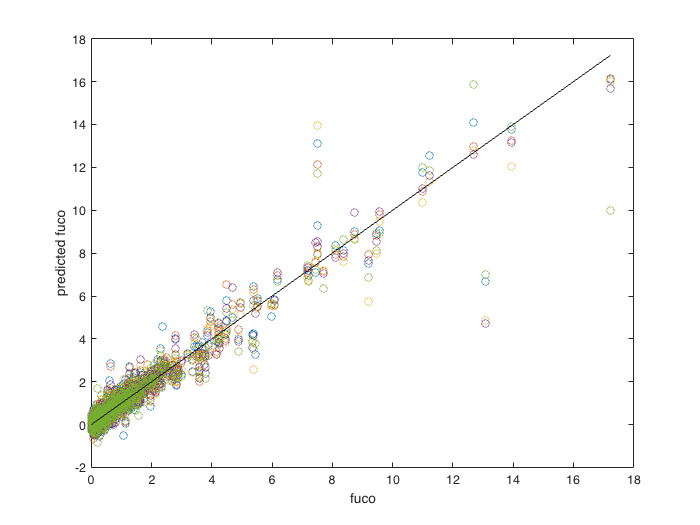

% get modeled pigments from each CV (with fancy matrix multiplication):
fuco_hat = (betas_fuco' * d2') + alphas_fuco'; 
mvchlb_hat = (betas_mvchlb' * d2') + alphas_mvchlb';
zea_hat = (betas_zea' * d2') + alphas_zea';

% plot to ensure each model is reasonable (or not):
figure(); hold on; box on;
scatter(fuco, fuco_hat, 'o');
plot(fuco, fuco, 'k-'); % 1:1 line
xlabel('fuco'); ylabel('predicted fuco');

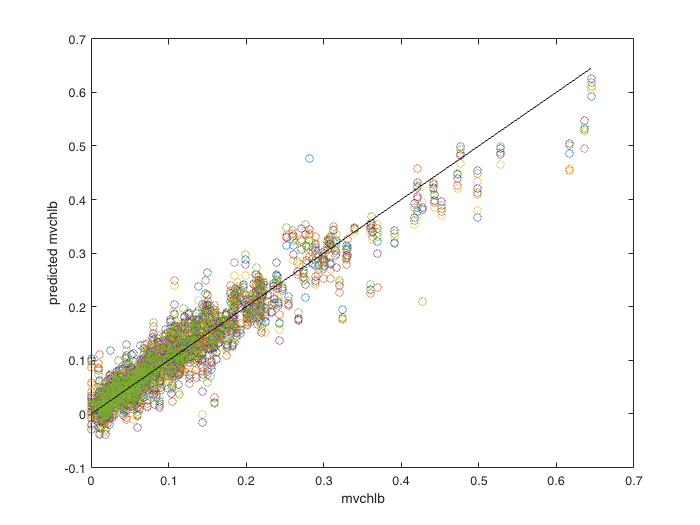


figure(); hold on; box on;
scatter(mvchlb, mvchlb_hat, 'o');
plot(mvchlb, mvchlb, 'k-'); % 1:1 line
xlabel('mvchlb'); ylabel('predicted mvchlb');

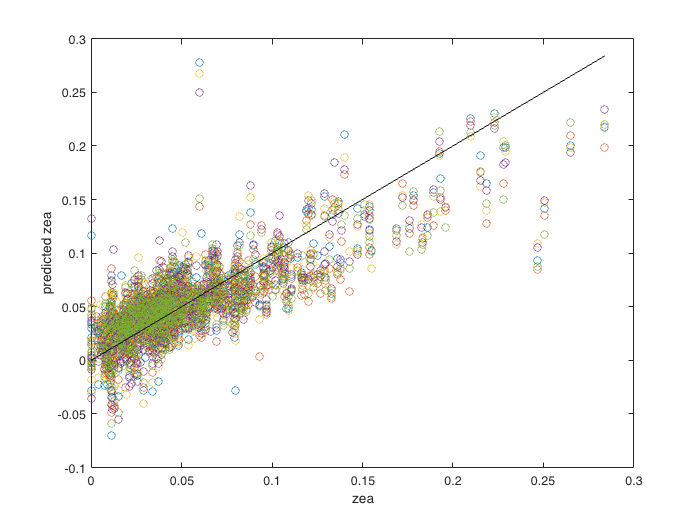


figure(); hold on; box on;
scatter(zea, zea_hat, 'o');
plot(zea, zea, 'k-'); % 1:1 line
xlabel('zea'); ylabel('predicted zea');

This is promising! Let's try to chop the data set up before model training and see how the predictions do for data that is totally out-of-domain. We saw previously that when we started, our data were organized chronologically, so by simply picking a point in the data set, we can roughly separate two distinct time periods and use one for model training and the other for evaluation:

idx = 0.75 * size(pigs, 1);

[betas_fuco, alphas_fuco, ~, ~, ~] = ...
    pig_from_aph_pcr_cv(d2(1:idx, :), fuco(1:idx),...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5


[betas_mvchlb, alphas_mvchlb, ~, ~, ~] = ...
    pig_from_aph_pcr_cv(d2(1:idx, :), mvchlb(1:idx),...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5


[betas_zea, alphas_zea, ~, ~, ~] = ...
    pig_from_aph_pcr_cv(d2(1:idx, :), zea(1:idx),...
    n_cv, cv_frac, mc, pred_select, mdl_select);

on CV number 1
on CV number 2
on CV number 3
on CV number 4
on CV number 5


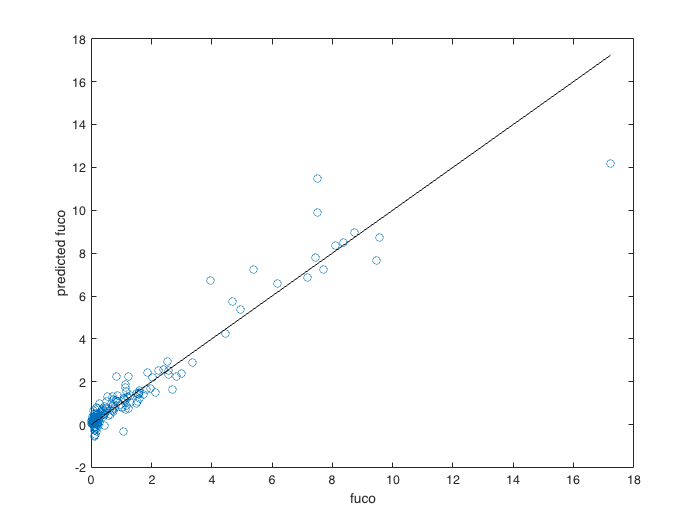


% validation data:
d2_val = d2(idx:end, :); 
fuco_val = fuco(idx:end);
mvchlb_val = mvchlb(idx:end);
zea_val = zea(idx:end);

% get modeled pigments:
% remember we have 5 sets of coefficients. We'll average them for our new
% predictions (so we're creating something like an ensemble):
fuco_hat = (mean(betas_fuco, 2)' * d2_val') + mean(alphas_fuco)'; 
mvchlb_hat = (mean(betas_mvchlb, 2)' * d2_val') + mean(alphas_mvchlb)';
zea_hat = (mean(betas_zea, 2)' * d2_val') + mean(alphas_zea)';

% plot:
figure(); hold on;box on;
scatter(fuco_val, fuco_hat);
plot(fuco_val, fuco_val, 'k-'); % 1:1 line
xlabel('fuco'); ylabel('predicted fuco');

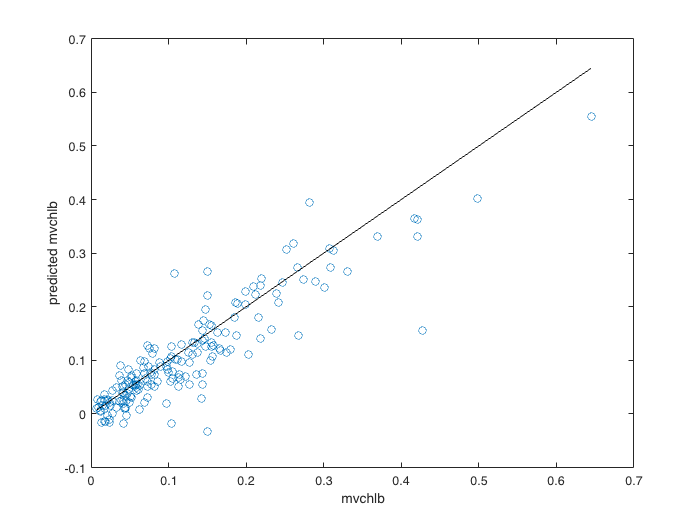


figure(); hold on;box on;
scatter(mvchlb_val, mvchlb_hat);
plot(mvchlb_val, mvchlb_val, 'k-'); % 1:1 line
xlabel('mvchlb'); ylabel('predicted mvchlb');

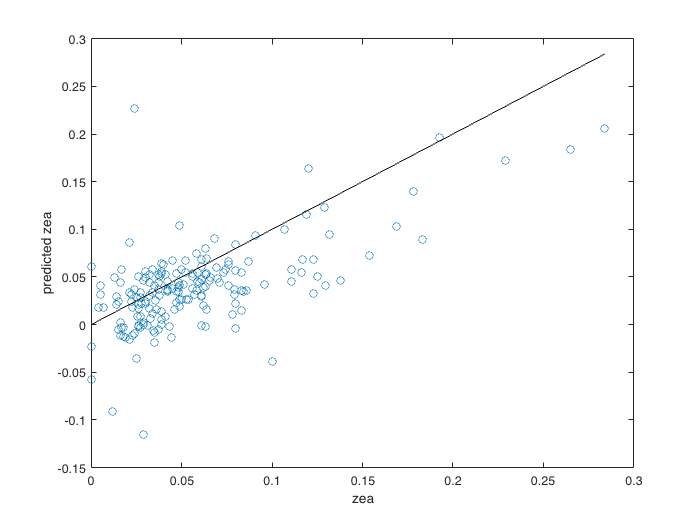


figure(); hold on;box on;
scatter(zea_val, zea_hat);
plot(zea, zea, 'k-'); % 1:1 line
xlabel('zea'); ylabel('predicted zea');

We get similar performance to what we saw in the cross-validation exercise, and this is certainly "science quality" performance in coastal marine environments. Hooray!